# Laplace Transform Lab: Solving ODEs using Laplace Transform in MATLAB

This lab will teach you to solve ODEs using a built in MATLAB Laplace transform function `laplace`.

There are five (5) exercises in this lab that are to be handed in. Write your solutions in a separate file, including appropriate descriptions in each step.

Include your name and student number in the submitted file.

## Student Information

## Using symbolic variables to define functions

In this exercise we will use symbolic variables and functions.

syms t s x y

f = cos(t)

$$f = \cos\left(t\right)$$

h = exp(2*x)

$$h = {\mathrm{e}}^{2\,x}$$

## Laplace transform and its inverse

% The routine |laplace| computes the Laplace transform of a function

F=laplace(f)

$$F = \frac{s}{s^{2}+1}$$

By default it uses the variable `s` for the Laplace transform But we can specify which variable we want:

H=laplace(h)

$$H = \frac{1}{s-2}$$

laplace(h,y)

$$ans = \frac{1}{y-2}$$


% Observe that the results are identical: one in the variable |s| and the
% other in the variable |y|

We can also specify which variable to use to compute the Laplace transform:

j = exp(x*t)

$$j = {\mathrm{e}}^{t\,x}$$

laplace(j)

$$ans = \frac{1}{s-x}$$

laplace(j,x,s)

$$ans = \frac{1}{s-t}$$


% By default, MATLAB assumes that the Laplace transform is to be computed
% using the variable |t|, unless we specify that we should use the variable
% |x|

We can also use inline functions with `laplace`. When using inline functions, we always have to specify the variable of the function.

l = @(t) t^2+t+1

l = function_handle with value:
    @(t)t^2+t+1


laplace(l(t))

$$ans = \frac{s+1}{s^{2}}+\frac{2}{s^{3}}$$

MATLAB also has the routine `ilaplace` to compute the inverse Laplace transform

ilaplace(F)

$$ans = \cos\left(t\right)$$

ilaplace(H)

$$ans = {\mathrm{e}}^{2\,t}$$

ilaplace(laplace(f))

$$ans = \cos\left(t\right)$$

If `laplace` cannot compute the Laplace transform, it returns an unevaluated call.

g = 1/sqrt(t^2+1)

$$g = \frac{1}{\sqrt{t^{2}+1}}$$

G = laplace(g)

$$G = \mathrm{laplace}\left(\frac{1}{\sqrt{t^{2}+1}},t,s\right)$$

But MATLAB "knows" that it is supposed to be a Laplace transform of a function. So if we compute the inverse Laplace transform, we obtain the original function

ilaplace(G)

$$ans = \frac{1}{\sqrt{t^{2}+1}}$$

The Laplace transform of a function is related to the Laplace transform of its derivative:

syms g(t)
laplace(diff(g,t),t,s)

$$ans = s\,\mathrm{laplace}\left(g\left(t\right),t,s\right)-g\left(0\right)$$

## Exercise 1

Objective: Compute the Laplace transform and use it to show that MATLAB 'knows' some of its properties.

Details: 

(a) Define the function `f(t)=exp(2t)*t^3`, and compute its Laplace transform `F(s)`. (b) Find a function `f(t)` such that its Laplace transform is  `(s - 1)*(s - 2))/(s*(s + 2)*(s - 3)` (c) Show that MATLAB 'knows' that if `F(s)` is the Laplace transform of  `f(t)`, then the Laplace transform of `exp(at)f(t)` is `F(s-a)` 

(in your answer, explain part (c) using comments). 

Observe that MATLAB splits the rational function automatically when solving the inverse Laplace transform.

% ============================================================================
% Exercise 1 Submission
% ============================================================================

% Define symbolic variables
syms t s

% (a)
% Define inline function
f(t) = exp(2*t)*(t^3);
% Compute (and display) laplace transform
F = laplace(f)

$$F = \frac{6}{{\left(s-2\right)}^{4}}$$


% (b)
% Define Laplace transformed function
G(s) = ((s-1)*(s-2))/(s*(s+2)*(s-3));
% Compute (and display) inverse
g = ilaplace(G)

$$g = \frac{6\,{\mathrm{e}}^{-2\,t}}{5}+\frac{2\,{\mathrm{e}}^{3\,t}}{15}-\frac{1}{3}$$


% (c)
syms q(t) p(t) a t

% Define function
q(t) = exp(a*t)*p(t);
% Compute laplace transforms
P = laplace(p)

$$P = \mathrm{laplace}\left(p\left(t\right),t,s\right)$$

Q = laplace(q)

$$Q = \mathrm{laplace}\left(p\left(t\right),t,s-a\right)$$


% When displaying the laplace transforms of the arbitrary functions p(t) and
% q(t) = exp(a*t)*p(t) (represented by P and Q, respectively), 
% MATLAB simply changes the last argument of the |laplace| routine from 
% |s| to |s-a|. In other words, MATLAB simply replaces the |s| parameter in
% P(s) with |s-a| to evaluate Q, meaning that MATLAB "knows" we can write 
% Q = P(s-a).

% ============================================================================

## Heaviside and Dirac functions

These two functions are builtin to MATLAB: `heaviside` is the Heaviside function `u_0(t)` at `0`

To define `u_2(t)`, we need to write

f=heaviside(t-2)

$$f = \mathrm{heaviside}\left(t-2\right)$$

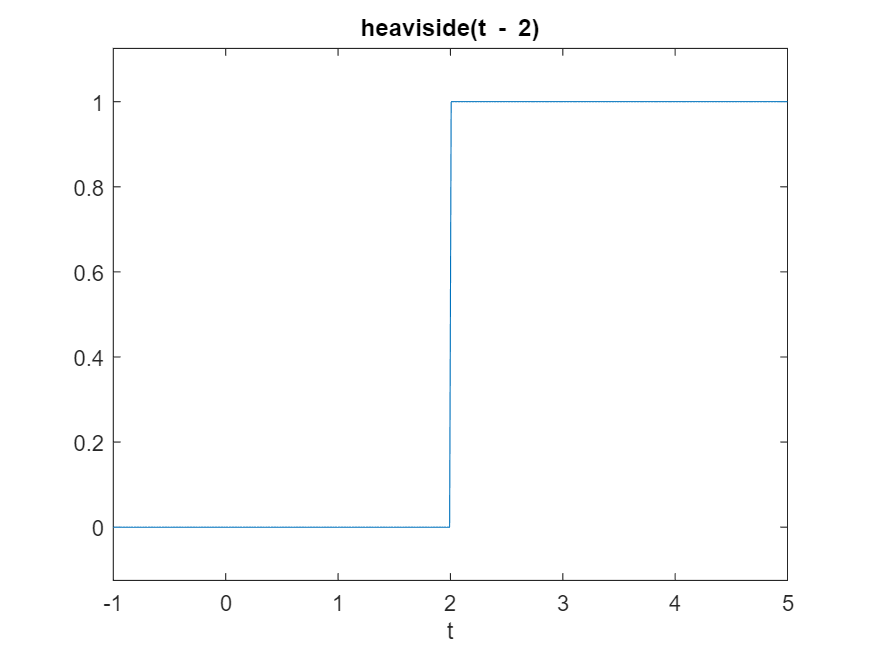

ezplot(f,[-1,5])


% The Dirac delta function (at |0|) is also defined with the routine |dirac|

g = dirac(t-3)

$$g = \delta (t-3)$$


% MATLAB "knows" how to compute the Laplace transform of these functions

laplace(f)

$$ans = \frac{{\mathrm{e}}^{-2\,s}}{s}$$

laplace(g)

$$ans = {\mathrm{e}}^{-3\,s}$$

## Exercise 2

Objective: Find a formula comparing the Laplace transform of a translation of `f(t)` by `t-a` with the Laplace transform of `f(t)`

Details: 

- Give a value to `a`

- Let `G(s)` be the Laplace transform of `g(t)=u_a(t)f(t-a)` and `F(s)` is the Laplace transform of `f(t)`, then find a formula relating `G(s)` and `F(s)`

In your answer, explain the 'proof' using comments.

% ============================================================================
% Exercise 2 Submission
% ============================================================================

syms u_a(t) f(t) g(t) t

for i = 1:5
    a = i
    % Define Heaviside function u_a(t) 
    u_a(t) = heaviside(t-a);

    % Define function g(t)
    g(t) = u_a(t)*f(t-a);

    % Compute and display Laplace transforms for several values of a
    F = laplace(f);
    G = laplace(g)
end

a = 1

$$G = {\mathrm{e}}^{-s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

a = 2

$$G = {\mathrm{e}}^{-2\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

a = 3

$$G = {\mathrm{e}}^{-3\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

a = 4

$$G = {\mathrm{e}}^{-4\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

a = 5

$$G = {\mathrm{e}}^{-5\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$


% As shown by the MATLAB output display, the Laplace transform G of g(t) =
% u_a(t)*f(t-a) is simply exp(-a*s)*F, where F is the Laplace transform of
% f(t) and a E [1,5] in this example.
% This outcome is corroborated by Theorem 5.5.1 in the textbook,
% which states that L{u_a(t)*f(t-a)} = exp(-a*s)*L{f(t)}. The proof of this
% theorem lies in a change of variables used to transform the integral
% (from c to infinity) of exp(-st)*f(t-c)dt to the integral of
% exp(-(z+c)*s)*f(x)dz, where z = t - c. Then, the exp(-c*s) term can be
% taken out of the integral since the integral is with respect to z, which
% results in L{u_a(t)*f(t-a)} = exp(-c*s) * integral from 0 to infinity of
% exp(-sz)*f(z)dz = exp(-c*s)*F(s). 
% ============================================================================

## Solving IVPs using Laplace transforms

Consider the following IVP, `y''-3y = 5t` with the initial conditions `y(0)=1` and `y'(0)=2`. We can use MATLAB to solve this problem using Laplace transforms:

% First we define the unknown function and its variable and the Laplace
% tranform of the unknown

syms y(t) t Y s

% Then we define the ODE

ODE=diff(y(t),t,2)-3*y(t)-5*t == 0

$$ODE = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-5\,t-3\,y\left(t\right)=0$$


% Now we compute the Laplace transform of the ODE.

L_ODE = laplace(ODE)

$$L\_ODE = s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-\frac{5}{s^{2}}-3\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=0$$


% Use the initial conditions

L_ODE=subs(L_ODE,y(0),1)

$$L\_ODE = s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-s-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)-\frac{5}{s^{2}}-3\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=0$$

L_ODE=subs(L_ODE,subs(diff(y(t), t), t, 0),2)

$$L\_ODE = s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-s-\frac{5}{s^{2}}-3\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-2=0$$


% We then need to factor out the Laplace transform of |y(t)|

L_ODE = subs(L_ODE,laplace(y(t), t, s), Y)

$$L\_ODE = Y\,s^{2}-s-3\,Y-\frac{5}{s^{2}}-2=0$$

Y=solve(L_ODE,Y)

$$Y = \frac{s+\frac{5}{s^{2}}+2}{s^{2}-3}$$


% We now need to use the inverse Laplace transform to obtain the solution
% to the original IVP

y = ilaplace(Y)

$$y = \cosh\left(\sqrt{3}\,t\right)-\frac{5\,t}{3}+\frac{11\,\sqrt{3}\,\sinh\left(\sqrt{3}\,t\right)}{9}$$

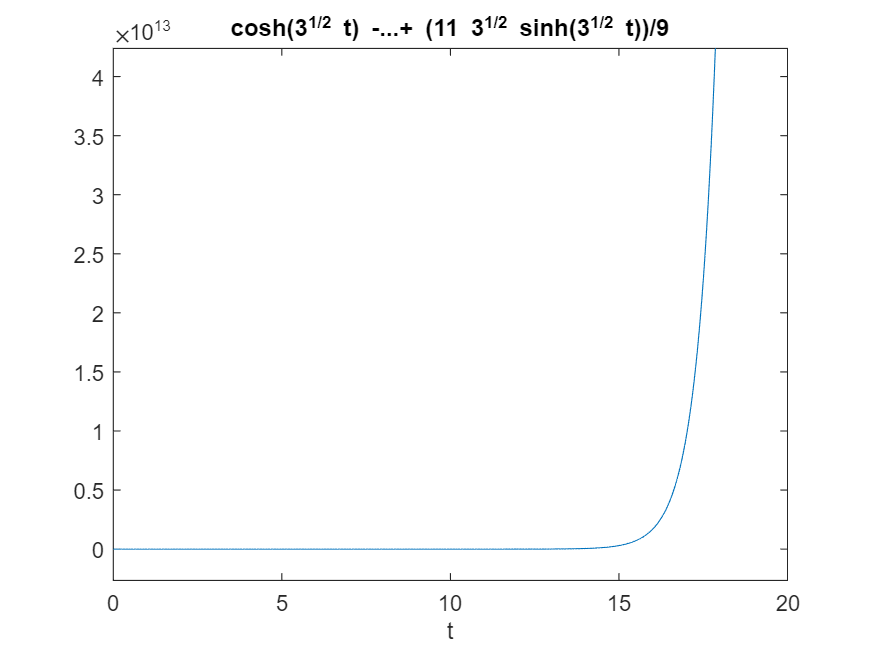


% We can plot the solution

ezplot(y,[0,20])


% We can check that this is indeed the solution

diff(y,t,2)-3*y

$$ans = 5\,t$$

## Exercise 3

Objective: Solve an IVP using the Laplace transform

Details: Explain your steps using comments

- Solve the IVP

- `y'''+2y''+y'+2*y=-cos(t)`

- `y(0)=0`, `y'(0)=0`, and `y''(0)=0`

- for `t` in `[0,10*pi]`

- Is there an initial condition for which `y` remains bounded as `t` goes to infinity? If so, find it.

% ============================================================================
% Exercise 3 Submission
% ============================================================================

% Define unknown function, independent variable and Laplace transform of
% the unknown function 
syms y(t) t Y s

% Define ODE
ODE = diff(y(t),t,3) + 2*diff(y(t),t,2) + diff(y(t),t,1) + 2*y(t) + cos(t) == 0;

% Compute Laplace transform of ODE
L_ODE = laplace(ODE);

% Use initial conditions
L_ODE = subs(L_ODE,y(0),0);
L_ODE = subs(L_ODE,subs(diff(y(t),t),t,0),0);
L_ODE = subs(L_ODE,subs(diff(y(t),t,2),t,0),0);

% Factor out Laplace transform of y(t) and solve for it
L_ODE = subs(L_ODE,laplace(y(t), t, s), Y)

$$L\_ODE = 2\,Y+Y\,s+\frac{s}{s^{2}+1}+2\,Y\,s^{2}+Y\,s^{3}=0$$

Y=solve(L_ODE,Y)

$$Y = -\frac{s}{\left(s^{2}+1\right)\,\left(s^{3}+2\,s^{2}+s+2\right)}$$


% Get (and display) the solution to the original IVP using the inverse Laplace transform 
y = ilaplace(Y)

$$y = \frac{2\,{\mathrm{e}}^{-2\,t}}{25}-\frac{2\,\cos\left(t\right)}{25}+\frac{3\,\sin\left(t\right)}{50}+\frac{t\,\cos\left(t\right)}{10}-\frac{t\,\sin\left(t\right)}{5}$$

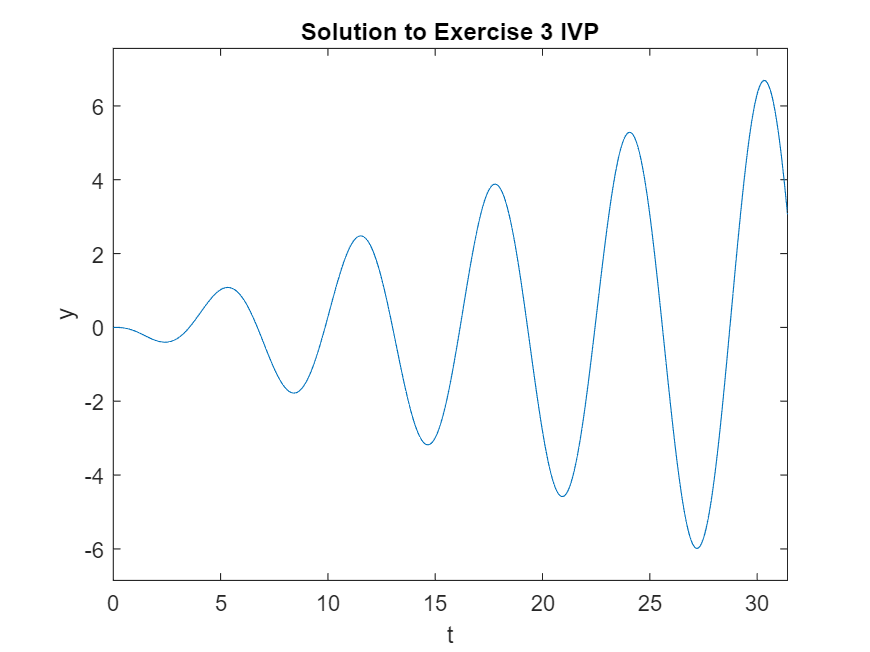


% Plot solution
ezplot(y,[0,10*pi]);
title('Solution to Exercise 3 IVP')
xlabel('t');
ylabel('y');


% Based on the solution to the problem, there is no intial condition for
% which y remains bounded as t goes to infinity. This is because the
% solution contains terms containing t multiplied by a sinusoidal function,
% which will always oscillate while increasing to infinity as t goes to
% infinity. Changing the initial conditions will not change this fundamental 
% form of the solution.
% ============================================================================

## Exercise 4

Objective: Solve an IVP using the Laplace transform

Details: 

- Define 

- `g(t) = 3 if 0 < t < 2`

- `g(t) = t+1 if 2 < t < 5`

- `g(t) = 5 if t > 5`

- Solve the IVP

- `y''+2y'+5y=g(t)`

- `y(0)=2 and y'(0)=1`

- Plot the solution for `t` in `[0,12]` and `y` in `[0,2.25]`.

In your answer, explain your steps using comments.

% ============================================================================
% Exercise 4 Submission
% ============================================================================

% Define unknown function, independent variable and Laplace transform of
% the unknown function 
syms y(t) t Y s

% Define heaviside functions for g(t)
u_0(t) = heaviside(t);
u_2(t) = heaviside(t-2);
u_5(t) = heaviside(t-5);

% Define g(t) using heaviside functions, whose "coefficients" can be found 
% by graphing each piecewise component.
g(t) = 3*u_0(t) + (t-2)*u_2(t) + (4-t)*u_5(t);

% Define ODE
ODE = diff(y(t),t,2) + 2*diff(y(t),t,1) + 5*y(t) - g(t) == 0;

% Compute Laplace transform of ODE
L_ODE = laplace(ODE);

% Use initial conditions
L_ODE = subs(L_ODE,y(0),2);
L_ODE = subs(L_ODE,subs(diff(y(t),t),t,0),1);

% Factor out Laplace transform of y(t) and solve for it
L_ODE = subs(L_ODE,laplace(y(t), t, s), Y)

$$L\_ODE = 5\,Y-2\,s+2\,Y\,s-\frac{{\mathrm{e}}^{-2\,s}}{s^{2}}+Y\,s^{2}-\frac{3}{s}+\frac{{\mathrm{e}}^{-5\,s}\,\left(s+1\right)}{s^{2}}-5=0$$

Y=solve(L_ODE,Y)

$$Y = \frac{2\,s+\frac{{\mathrm{e}}^{-2\,s}}{s^{2}}+\frac{3}{s}-\frac{{\mathrm{e}}^{-5\,s}\,\left(s+1\right)}{s^{2}}+5}{s^{2}+2\,s+5}$$


% Get (and display) the solution to the original IVP using the inverse Laplace transform 
y = ilaplace(Y)

$$y = \begin{array}{l} \mathrm{heaviside}\left(t-2\right)\,\left(\frac{t}{5}+\frac{2\,{\mathrm{e}}^{2-t}\,\left(\cos\left(2\,t-4\right)-\frac{3\,\sin\left(2\,t-4\right)}{4}\right)}{25}-\frac{12}{25}\right)-\mathrm{heaviside}\left(t-5\right)\,\left(\frac{t}{5}+\frac{2\,{\mathrm{e}}^{5-t}\,\left(\sigma_{3}-\frac{3\,\sigma_{2}}{4}\right)}{25}-\frac{27}{25}\right)+2\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)-\sigma_{1}\right)-\frac{3\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+\sigma_{1}\right)}{5}+\frac{5\,\sin\left(2\,t\right)\,{\mathrm{e}}^{-t}}{2}+\mathrm{heaviside}\left(t-5\right)\,\left(\frac{{\mathrm{e}}^{5-t}\,\left(\sigma_{3}+\frac{\sigma_{2}}{2}\right)}{5}-\frac{1}{5}\right)+\frac{3}{5}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(2\,t\right)}{2}\\ \sigma_{2}=\sin\left(2\,t-10\right)\\ \sigma_{3}=\cos\left(2\,t-10\right) \end{array}$$

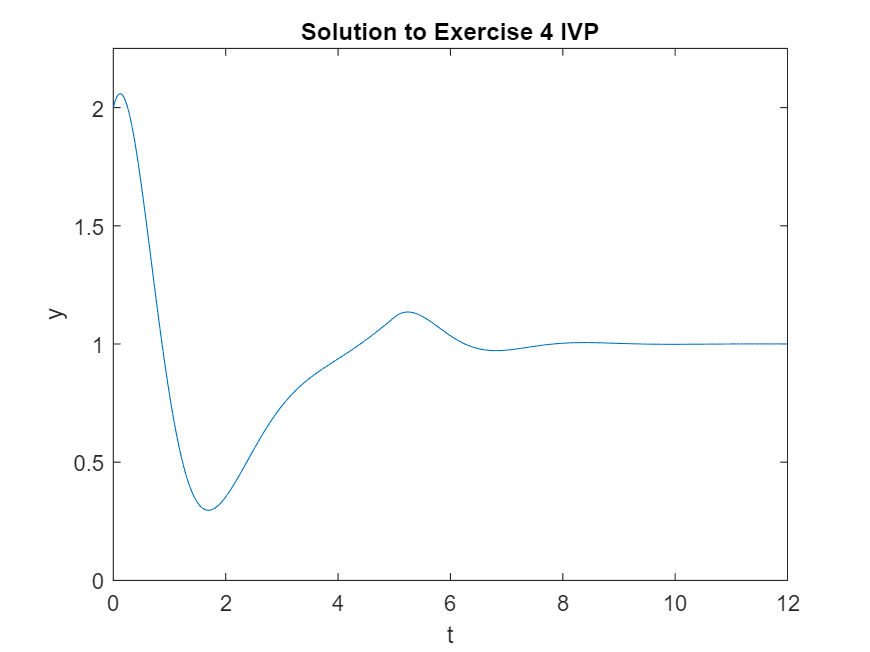


% Plot solution
ezplot(y,[0,12,0,2.25]);
title('Solution to Exercise 4 IVP')
xlabel('t');
ylabel('y');


% ============================================================================

## Exercise 5

Objective: Use the Laplace transform to solve an integral equation

Verify that MATLAB knowns about the convolution theorem by explaining why the following transform is computed correctly.

% ============================================================================
% Exercise 5 Submission
% ============================================================================

syms t tau y(tau) s
I=int(exp(-2*(t-tau))*y(tau),tau,0,t)

$$I = \int_{0}^{t}{\mathrm{e}}^{2\,\tau -2\,t}\,y\left(\tau \right)\mathrm{d}\tau$$

laplace(I,t,s)

$$ans = \frac{\mathrm{laplace}\left(y\left(t\right),t,s\right)}{s+2}$$


% The Convolution Theorem (5.8.3) states that for two functions f and g, 
% the Laplace transform of f convolved with g is equal to the product of
% the individual Laplace transforms of f and g (i.e. L{h(t)} = F(s)*G(s)
% where h(t) = integral from 0 to t of f(t-tau)*g(tau)d(tau)).

% In the case of the above transform, we can take f(t) = exp(-2*t) as convolved
% with some arbitrary function g(t) = y(t). The laplace transform of this
% convolution is taken in the following line and the result is displayed.

% We can prove that MATLAB computes the transform correctly by writing out
% explicitly the product of the two individual Laplace transforms:

syms f(t) g(t)

f(t) = exp(-2*t);

F = laplace(f)

$$F = \frac{1}{s+2}$$

G = laplace(y)

$$G = \mathrm{laplace}\left(y\left(\tau \right),\tau ,s\right)$$


H = F * G

$$H = \frac{\mathrm{laplace}\left(y\left(\tau \right),\tau ,s\right)}{s+2}$$


% Since H(s) = F(s)*G(s) is the same as the above output (given by laplace(I,t,s), 
% by the convolution theorem, we know that MATLAB computed the transform correctly.

% ============================================================================